# 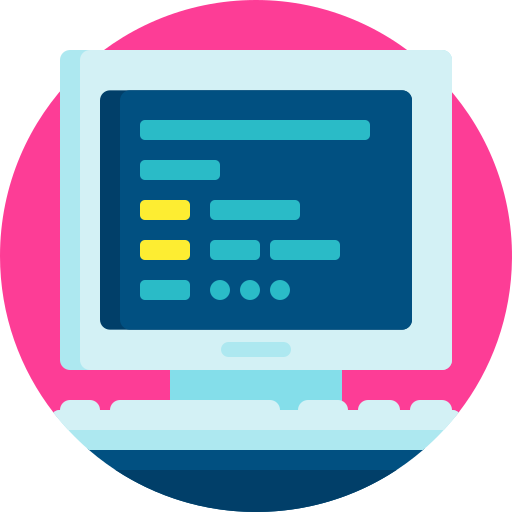

# Virtual Lab 4 - Orientation estimation

#### This Virtual Lab covers Section 4.1-4.4.1.2 of the course notes

- This Virtual Lab will require both pen-on-paper work, as well as the use of MATLAB coding. The intention is to be able to solve the problems on paper (as you would in a Test/Exam) and then ratify the result using MATLAB.

- Make sure to save this file somewhere where you can access it again later, e.g. Google Drive/OneDrive/MATLAB Drive/USB. 

- This live script is intended to be used with the code shown. Select the `VIEW` tab and switch to `Output Inline`.

- Each Section of this Live Script must be run individually. You can run Sections by using the `Run Section` button under the `LIVE EDITOR` ribbon (at the top of the screen), or using CNTL+ENTER (or CMD+ENTER).

### Gyroscopes

Any sensor that measures the rate of change of orientation is known as a gyroscope. The gyroscope found in an IMU provides a convenient measure of rotational velocity. If the sensor is correctly calibrated, the measurement is very reliable and can often be provided at high sampling rates of over $1$kHz. As we will show in the following subsections, gyroscopes struggle when estimating orientation over time due to an effect known as drift — the result of accumulated integration error. 

#### Measurement equation

Assuming the IMU frame is aligned with $\{B\}$, the generalised measurement equation of a gyroscope is given by


$${^B{\bf \omega}^\#}={^B{\bf \omega}}+{\bf b}_\omega+{\bf n}_\omega,$$


where ${^B{\bf \omega}}$ is the true angular velocity experienced by the sensor (and by extension, frame $\{B\}$), ${^B{\bf \omega}^\#}$ is the measured signal, with the superscript $\#$ indicating a measured quantity, ${{\bf b}_\omega}$ is an unknown and time-varying bias term, and ${{\bf n}_\omega}$ is nondeterministic measurement noise, which is often treated as white noise.

#### Bias compensation

The unknown bias term of ${{\bf b}_\omega}$ needs to be accounted for when estimating angular velocity. Angular velocity bias is temperature dependent and has an approximately linear relationship with incremental changes in temperature. For this reason, most MEMS IMUs also include temperature sensing modules to actively account for this. The bias term can be approximately inferred from IMU temperature based on


$${{\bf b}^+_\omega} =  {{\bf b}_\omega}(0)+{\bf c} \Delta T^\#,$$


where ${{\bf b}^+_\omega} $ is the estimated bias term, with the superscript of $+$ indicating the parameter is an estimate, ${{\bf b}_\omega}(0)$ is the initial bias term at time $t=0$, ${\bf c}$ is a vector of gradient coefficients, and $\Delta T^\#$ is the measured differential temperature on the IMU.

If the IMU is constrained such that angular velocity is not experienced, ${^B{\bf \omega}^}={\bf 0}$, the measurement equation becomes


$$\begin{array}{ll}
{^B{\bf \omega}^\#}
&={\bf b}_\omega+{\bf n}_\omega,\\
&\approx {{\bf b}_\omega}(0)+{\bf c} \Delta T^\#+{\bf n}_\omega.
\end{array}$$


In this configuration, as the gyroscope experiences an increase of temperate, a corresponding straight line response will be seen on each channel of the gyroscope, with the respective y-intercepts corresponding to ${{\bf b}_\omega}(0)$, and the gradients corresponding to the elements of $\bf c$. One can therefore *de-bias* the gyroscope reading using ${{\bf b}_\omega^+}$ if the sensor has been calibrated, which yields an estimate for the angular velocity of


$$\begin{array}{ll}
{^B{\bf \omega}^+}
&={^B{\bf \omega}^\#}-{{\bf b}^+_\omega},\\
&={^B{\bf \omega}}+\left({\bf b}_\omega-{{{\bf b}^+_\omega}}\right)+{\bf n}_\omega, \\
&\approx{^B{\bf \omega}}+{\bf n}_\omega.
\end{array}$$


#### Example: Calibrating a gyroscope

The code block below provides a simulated example of the effects of gyroscope bias, as well as how to actively compensate for it.

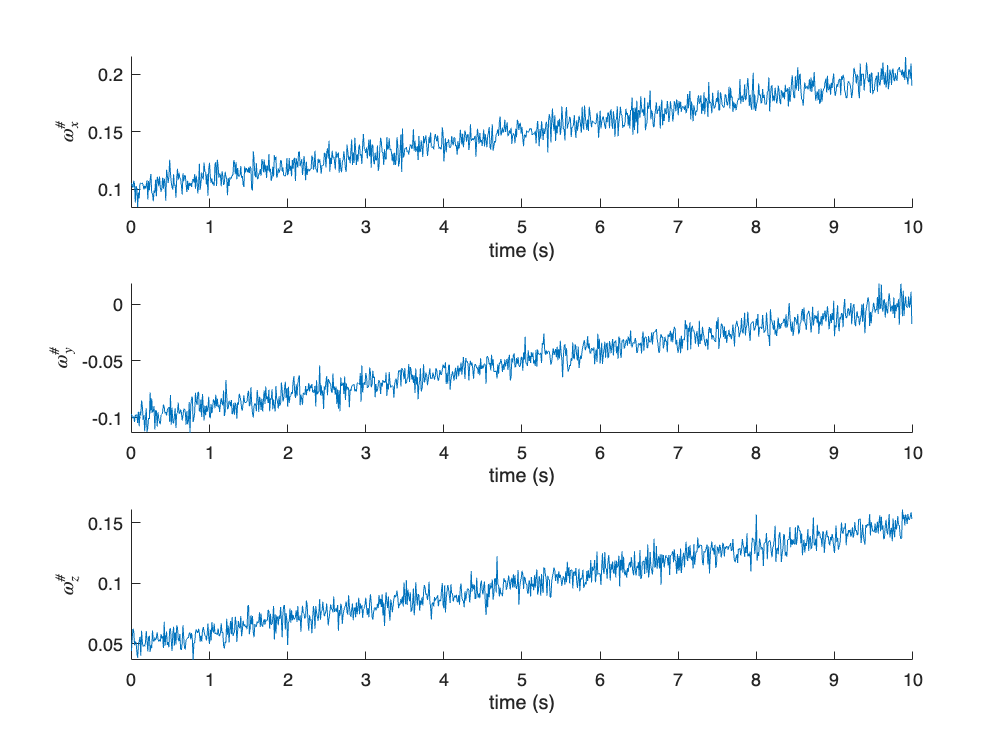

IMU = imuSensor;    %initialise simulated IMU
IMU.Gyroscope.NoiseDensity = 1e-3;    %set gyroscope noise density
IMU.Gyroscope.ConstantBias = [0.1 -0.1 0.05];    %set gyroscope bias
IMU.Gyroscope.TemperatureBias = 1e-3*ones(1,3);    %set gyroscope temperature gradient
IMU.Temperature = 25;    %set initial IMU temperature

dT = 0.01;    %sampling duration
numSamples = 1000;    %number of samples
t = (0:numSamples-1)*dT;    %time vector

omega = zeros(1,3);    %zero angular velocity
omege_meas = zeros(numSamples,3);    %initialised measured angular velocity 
temp = zeros(numSamples,1);

for k=1:numSamples
    [~,omega_meas(k,:)] = IMU(zeros(1,3),omega);    %generate simulated gyroscope measurements using IMU
    temp(k) = IMU.Temperature;                      %save current IMU temperate
    IMU.Temperature = IMU.Temperature+0.1;          %increase IMU temperature by 0.1 degrees
end

%plot figure
figure,
subplot(3,1,1), hold on
plot(t,omega_meas(:,1)),xlabel('time (s)'),ylabel('$\omega^\#_x$',Interpreter='latex')
subplot(3,1,2),hold on
plot(t,omega_meas(:,2)),xlabel('time (s)'),ylabel('$\omega^\#_y$',Interpreter='latex')
subplot(3,1,3),hold on
plot(t,omega_meas(:,3)),xlabel('time (s)'),ylabel('$\omega^\#_z$',Interpreter='latex')

We can fit a straight line to this data using MATLAB (or roughly by hand), which gives the following behaviour.

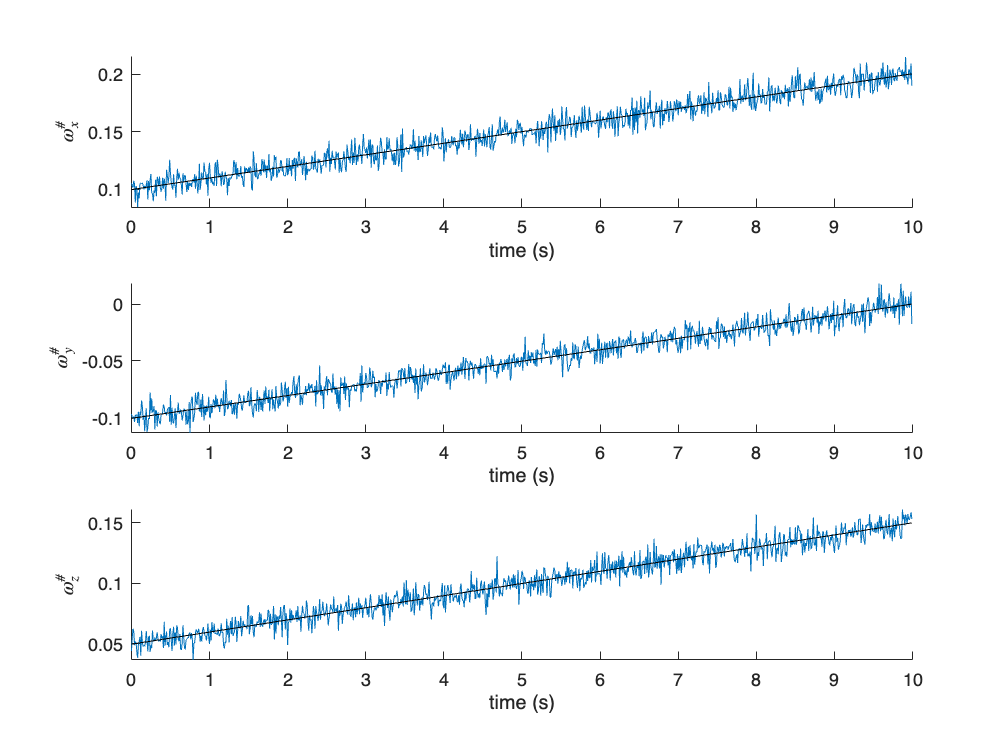

p1 = polyfit(temp-temp(1),omega_meas(:,1),1);    %fit first-order polynomial to angular velocity data
p2 = polyfit(temp-temp(1),omega_meas(:,2),1);
p3 = polyfit(temp-temp(1),omega_meas(:,3),1);

b = zeros(numSamples,3);                         %initialise bias vector
b(:,1) = p1(2)+p1(1)*(temp-temp(1));             %determine bias estimate using polynomial coefficients
b(:,2) = p2(2)+p2(1)*(temp-temp(1));
b(:,3) = p3(2)+p3(1)*(temp-temp(1));

%plot figure
figure,
subplot(3,1,1), hold on
plot(t,omega_meas(:,1)),xlabel('time (s)'),ylabel('$\omega^\#_x$',Interpreter='latex')
plot(t,b(:,1),'k')
subplot(3,1,2),hold on
plot(t,omega_meas(:,2)),xlabel('time (s)'),ylabel('$\omega^\#_y$',Interpreter='latex')
plot(t,b(:,2),'k')
subplot(3,1,3),hold on
plot(t,omega_meas(:,3)),xlabel('time (s)'),ylabel('$\omega^\#_z$',Interpreter='latex')
plot(t,b(:,3),'k')

Using $\begin{array}{ll}
{^B{\bf \omega}^+}
&={^B{\bf \omega}^\#}-{{\bf b}^+_\omega}
\end{array}$, we can plot the resulting estimated angular velocity, which we know should be equal to zero.

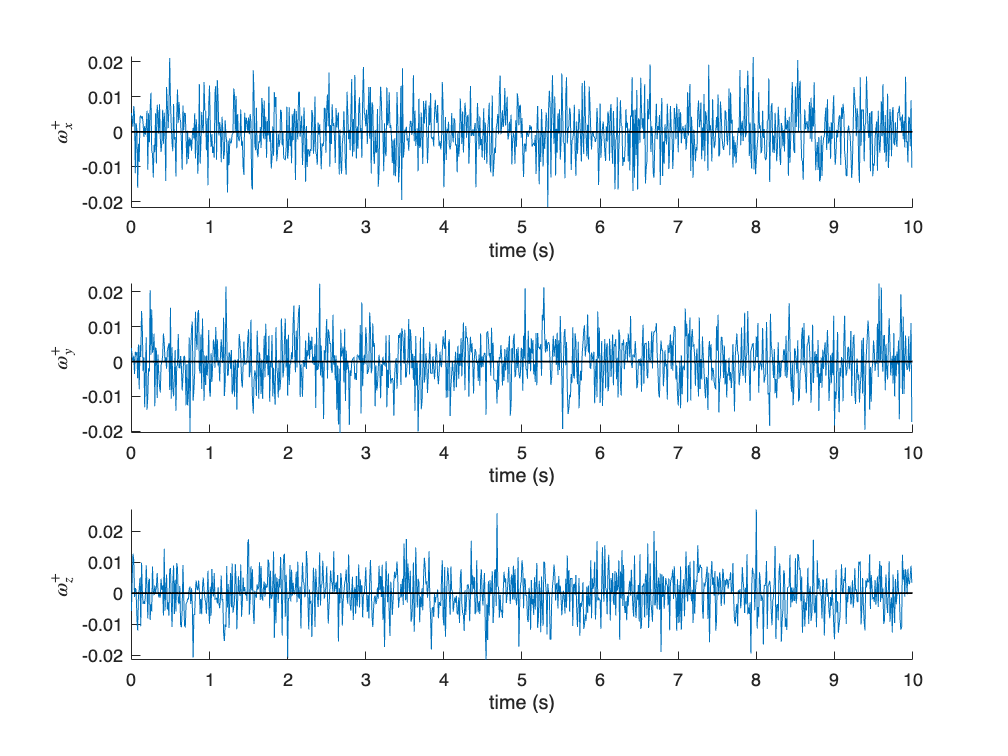

%plots of angular velocity after measurement has been de-biased
figure,
subplot(3,1,1), hold on
plot(t,omega_meas(:,1)-b(:,1)),xlabel('time (s)'),ylabel('$\omega^+_x$',Interpreter='latex')
line(xlim, [0,0], 'Color', 'k', 'LineWidth', 1); % Draw line for X axis.
subplot(3,1,2),hold on
plot(t,omega_meas(:,2)-b(:,2)),xlabel('time (s)'),ylabel('$\omega^+_y$',Interpreter='latex')
line(xlim, [0,0], 'Color', 'k', 'LineWidth', 1); % Draw line for X axis.
subplot(3,1,3),hold on
plot(t,omega_meas(:,3)-b(:,3)),xlabel('time (s)'),ylabel('$\omega^+_z$',Interpreter='latex')
line(xlim, [0,0], 'Color', 'k', 'LineWidth', 1); % Draw line for X axis.

While noise is still present, the bias term has clearly been removed.

#### Estimating orientation using rotation matrices

Recall from **Chapter 3** that if the angular velocity is exactly known for a period of $\Delta t$ units of time, the incremental exponential coordinates are given by


$${^B\Delta{\bf \theta}={^B{\bf \omega}}\Delta t.$$


The incremental axis-angle form was given by


$$\Delta \alpha=|{^B{\bf \omega}}|\Delta t,$$
           
$${^B\hat{\bf \omega}}=\frac{^B{\bf \omega}}{|{^B{\bf \omega}}|},$$


and the corresponding incremental rotation matrix was


$$\begin{array}{ll}
\Delta{\bf R}
&=\mathrm{e}^{\lfloor {^B{\Delta\bf \theta}} \rfloor},\\
&=\mathrm{e}^{\lfloor {^B{\bf \omega}}\Delta t \rfloor},\\
&={\bf I}+\sin\Delta\alpha\lfloor ^B\hat{\bf \omega} \rfloor +\left(1-\cos\Delta\alpha\right)\lfloor ^B\hat{\bf \omega} \rfloor^2,\\
&={\bf I}+\sin(|{^B{\bf \omega}}|\Delta t)\lfloor ^B\hat{\bf \omega} \rfloor +\left(1-\cos(|{^B{\bf \omega}}|\Delta t)\right)\lfloor ^B\hat{\bf \omega} \rfloor^2.
\end{array}
$$


Assuming that the angular velocity measurement has been sufficiently de-biased, one can similarly integrate ${^B{\bf \omega}^+}$ to obtain an orientation *estimate*. Replacing ${^B{\bf\omega}}$ with ${^B{\bf\omega}^+}$ for the above equations yields


$${^B\Delta{\bf \theta}^+={^B{\bf \omega}^+}\Delta t,$$
     
$$\Delta \alpha^+=|{^B{\bf \omega}^+}|\Delta t,$$
      
$${^B\hat{\bf \omega}^+}=\frac{^B{\bf \omega}^+}{|{^B{\bf \omega}^+}|},$$


and 


$$\begin{array}{ll}
\Delta{\bf R}^+
&=\mathrm{e}^{\lfloor {^B{\Delta{\bf \theta}^+}} \rfloor},\\
&=\mathrm{e}^{\lfloor {^B{\bf \omega}^+}\Delta t \rfloor},\\
&={\bf I}+\sin\Delta\alpha^+\lfloor ^B\hat{\bf \omega}^+ \rfloor +\left(1-\cos\Delta\alpha^+\right)\lfloor ^B\hat{\bf \omega}^+ \rfloor^2,\\
&={\bf I}+\sin(|{^B{\bf \omega}^+}|\Delta t)\lfloor ^B\hat{\bf \omega}^+ \rfloor +\left(1-\cos(|{^B{\bf \omega}^+}|\Delta t)\right)\lfloor ^B\hat{\bf \omega}^+ \rfloor^2.
\end{array}
$$


An estimated angular velocity experienced by a rigid body that moves it from frame $\{0\}$ to $\{1\}$ over a period of $\Delta t$ units is then described by


$${^W{\bf R}^+_{\{1\}}}={^W{\bf R}^+_{\{0\}}}{^{\{0\}}{\bf R}^+_{\{1\}},$$
 

where $\Delta{\bf R}^+={^{\{0\}}{\bf R}^+_{\{1\}}
$ is the incremental orientation as a result of the body-frame angular velocity. 

In practice, angular velocity measurements will be obtained from a gyroscope at discrete intervals, as opposed to being a continuous signal. If we make the assumption that the angular velocity is constant during each sampling instance of length $\Delta t$, then we can define our incremental rotation at sample time $k$ as 


$$\begin{array}{ll}
\Delta{\bf R}^+_k
&={^{\{k-1\}}{\bf R}_{\{k\}},\\
&=\mathrm{e}^{\lfloor {^B{\bf \omega}^+_k}\Delta t \rfloor},\\
&={\bf I}+\sin\Delta\alpha^+_k\lfloor ^B\hat{\bf \omega}^+_k \rfloor +\left(1-\cos\Delta\alpha^+_k\right)\lfloor ^B\hat{\bf \omega}^+_k \rfloor^2,\\
&={\bf I}+\sin(|{^B{\bf \omega}^+_k}|\Delta t)\lfloor ^B\hat{\bf \omega}^+_k \rfloor +\left(1-\cos(|{^B{\bf \omega}^+_k}|\Delta t)\right)\lfloor ^B\hat{\bf \omega}^+_k \rfloor^2.
\end{array}
$$


The estimated orientation at sample instance $k$ follows as


$$\begin{array}{ll}
{^W{\bf R}^+_{\{k\}}}
&={^W{\bf R}^+_{\{0\}}}{^{\{0\}}{\bf R}^+_{\{1\}} \dots {^{\{k-1\}}{\bf R}^+_{\{k\}},\\
&={^{W}{\bf R}^+_{\{k-1\}} {^{\{k-1\}}{\bf R}^+_{\{k\}},\\
\end{array}$$
 

where each rotation matrix estimate is obtained from a particular sampling instance, after integrating the angular velocity and then applying the exponential coordinate mapping. 

The angular velocity estimate ${^B{\bf \omega}^+}$ is notably imperfect, as a result of 

- non-zero sensor resolution (from the ADC conversion), 

- noise term ${\bf n}_\omega$, 

- as well as the potential biasing as a result of ${{{\bf b}^+_\omega}}\neq{\bf b}_\omega$. 

Additionally, the assumption that the estimated angular velocity is constant for the entire duration of the sampling period will also result in an imperfect estimate of the incremental exponential coordinates, based on ${^B\Delta{\bf \theta}^+={^B{\bf \omega}^+}\Delta t$. For this reason, the orientation estimate using the approach outlined above will ultimately experience drift (or random walk) that cannot be compensated for. The result is that the orientation estimate will become less reliable over time, as the errors from the imperfect angular velocity estimate and sampling assumptions continue to accumulate. This problem can be solved using sensor fusion.

#### Estimating orientation using quaternions

As shown in **Chapter 3**, The quaternion is an alternative approach to determining orientation from angular velocity information. Given an angular velocity estimate of ${^B{\bf \omega}^+_k}$ at sample instance $k$, the angle-axis representation of the incremental rotation can be determined by


$$\Delta \alpha^+_k=|{^B{\bf \omega}^+_k}|\Delta t,$$
      
$${^B\hat{\bf \omega}^+_k}=\frac{^B{\bf \omega}^+_k}{|{^B{\bf \omega}^+_k}|},$$


which is equivalent to the axis-angle representation of the incremental exponential coordinates from the previous section. The estimated incremental quaternion at sample instance $k$ follows as


$$\begin{array}{cc}\Delta{\mathbf q}^+_k =
{^{\{k-1\}}{\bf q}^+_{\{k\}}
= \left[\begin{array}{cc}    \cos{\frac{\Delta\alpha^+_k}{2}} \\ \sin{\frac{\Delta\alpha^+_k}{2}} {^B\hat{\mathbf \omega}^+_k}     \\ \end{array}\right],\end{array}$$


with the absolute estimated quaternion given by


$$\begin{array}{ll}
{^W{\bf q}^+_{\{k\}}}
&={^W{\bf q}^+_{\{0\}}}\otimes{^{\{0\}}{\bf q}^+_{\{1\}}\otimes \dots \otimes{^{\{k-1\}}{\bf q}^+_{\{k\}}, \\
&={^W{\bf q}^+_{\{k-1\}}} \otimes{^{\{k-1\}}{\bf q}^+_{\{k\}}.
\end{array}$$
 

As with the rotation matrix approach, estimating the quaternion orientation using only estimated (and imperfect) angular velocity information will result in orientation errors over time.

#### Example: Estimating orientation from a gyroscope

The code block below provides a simulation of an IMU with adjustable noise. With negligible noise, the orientation estimates are reliable over the full length of the simulation, but with increasing noise the accuracy drops significantly.

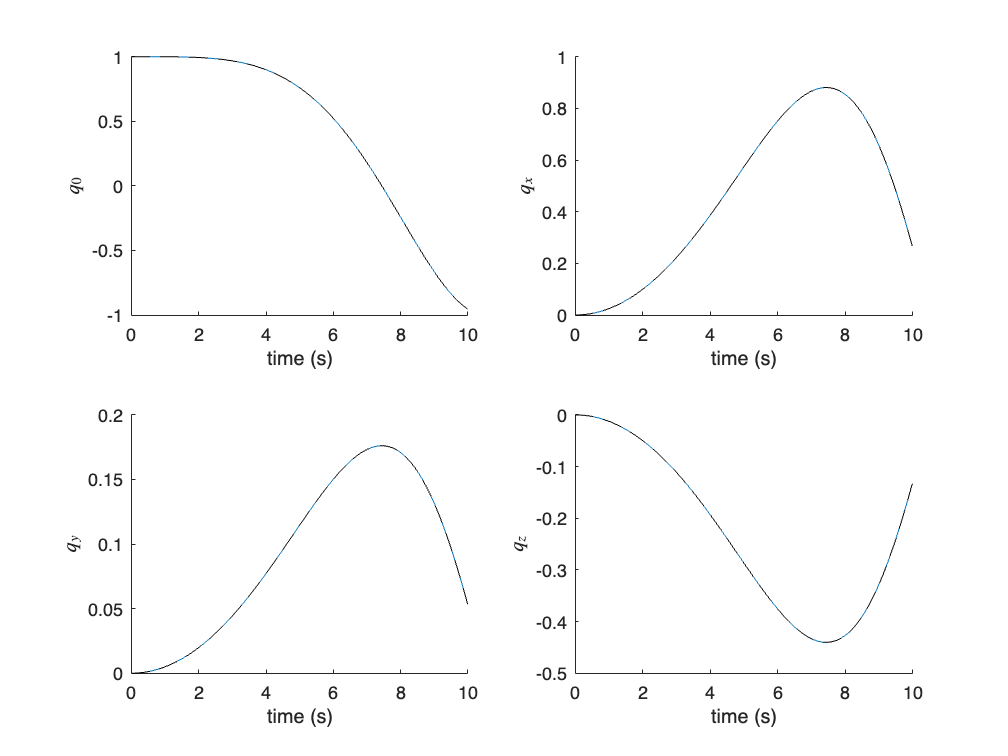

IMU = imuSensor;    %initialise simulated IMU
IMU.Gyroscope.NoiseDensity = 0.00001;    %set gyroscope noise density
dT = 0.01;    %set sampling time
numSamples = 1000;    %set number of samples
t = (0:numSamples-1)*dT;    %set time vector

omega1 = linspace(0,1,numSamples);
omega2 = linspace(0,0.2,numSamples);
omega3 = linspace(0,-0.5,numSamples);
omega = [omega1' omega2' omega3'];    %define arbitrary angular velocity


q_ = zeros(numSamples,4);    %initialise estimated quaternion array
q_(1,1:4) = [1 0 0 0];
q = q_;

for k=1:numSamples-1
    %actual
    dtheta = omega(k,:)*dT;    %incremental exponential coordinates
    dalpha = norm(dtheta);     %incremental rotation angle
    if( dalpha == 0)           %incremental rotation vector
        v = [0 0 0];
    else
        v = dtheta/dalpha;
    end
    dq = [cos(dalpha/2) sin(dalpha/2)*v];    %incremental quaternion
    q(k+1,1:4) = quatmultiply(q(k,1:4),dq);    %update quaternion
    q(k+1,1:4) = q(k+1,1:4)/norm( q(k+1,1:4) );

    %measurement
    [~,omega_meas] = IMU(zeros(1,3),omega(k,:));    %obtain simulated gyroscope reading
    
    %estimate
    dtheta_ = omega_meas*dT;    %estimated incremental exponential coordinates
    dalpha_ = norm(dtheta_);    %estimated incremental rotation angle
    if( dalpha_ == 0 )          %estimated incremental rotation vector
        v_ = [0 0 0];
    else
        v_ = dtheta_/dalpha_;
    end
    dq_ = [cos(dalpha_/2) sin(dalpha_/2)*v_];    %estimated incremental quaternion
    q_(k+1,1:4) = quatmultiply(q_(k,1:4),dq_);    %update estimated quaternion
    q_(k+1,1:4) = q_(k+1,1:4)/norm( q_(k+1,1:4) );
end

%plot figures
figure
subplot(2,2,1),hold on
plot(t,q_(:,1)),plot(t,q(:,1),'--k'),ylabel('$q_0$',Interpreter='latex'),xlabel('time (s)')
subplot(2,2,2),hold on
plot(t,q_(:,2)),plot(t,q(:,2),'--k'),ylabel('$q_x$',Interpreter='latex'),xlabel('time (s)')
subplot(2,2,3),hold on
plot(t,q_(:,3)),plot(t,q(:,3),'--k'),ylabel('$q_y$',Interpreter='latex'),xlabel('time (s)')
subplot(2,2,4),hold on
plot(t,q_(:,4)),plot(t,q(:,4),'--k'),ylabel('$q_z$',Interpreter='latex'),xlabel('time (s)')

The partially completed code below has been provided for a different arbitrary motion.

**  Question 1: **Complete the algorithm so that rotation matrices are used instead of quaternions when performing the estimation. Set the gyroscope noise density to zero to verify the result. Use variable `R_` for the rotation matrix estimate. Paste your final code (the entire code block) into the Amathuba answer block. Your student number must be in the figure title, using the function *sgtitle.*

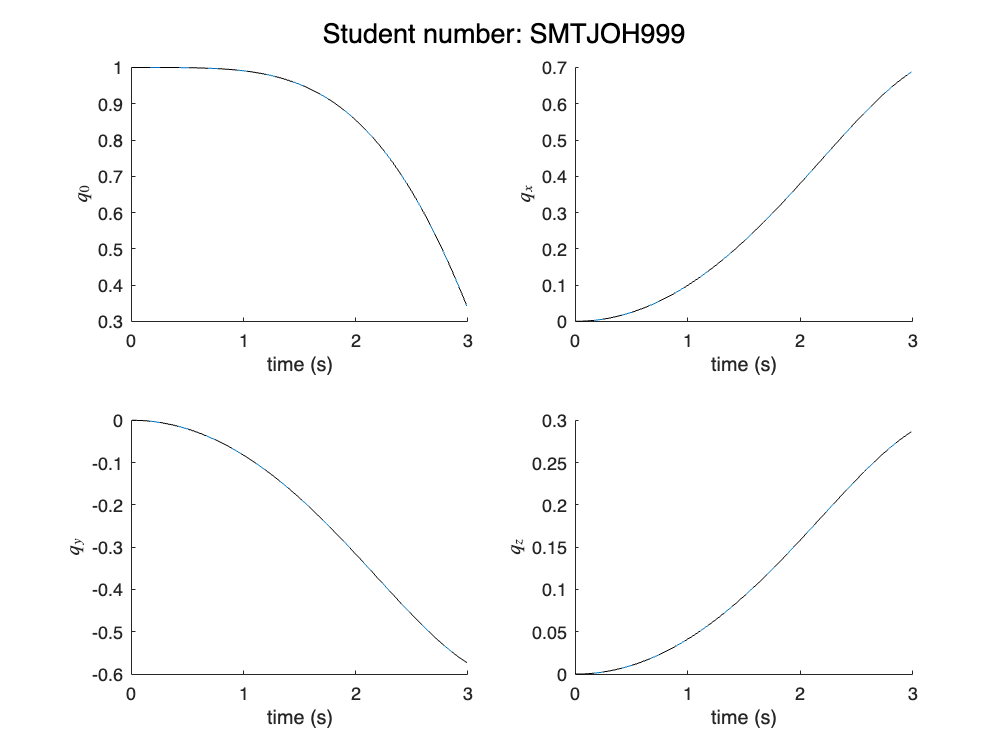

IMU = imuSensor;    %initialise simulated IMU
IMU.Gyroscope.NoiseDensity = 0;    %set gyroscope noise density
dT = 0.01;    %set sampling time
numSamples = 300;    %set number of samples
t = (0:numSamples-1)*dT;    %set time vector

omega1 = linspace(0,1.2,numSamples);
omega2 = linspace(0,-1,numSamples);
omega3 = linspace(0,0.5,numSamples);
omega = [omega1' omega2' omega3'];    %define arbitrary angular velocity


R_ = zeros(3,3,numSamples);    %initialise estimated quaternion array
R_(:,:,1) = eye(3,3);
q = zeros(numSamples,4);
q(1,:) = [1 0 0 0];

for k=1:numSamples-1
    %actual
    dtheta = omega(k,:)*dT;    %incremental exponential coordinates
    dalpha = norm(dtheta);     %incremental rotation angle
    if( dalpha == 0)           %incremental rotation vector
        v = [0 0 0];
    else
        v = dtheta/dalpha;
    end
    dq = [cos(dalpha/2) sin(dalpha/2)*v];    %incremental quaternion
    q(k+1,1:4) = quatmultiply(q(k,1:4),dq);    %update quaternion
    q(k+1,1:4) = q(k+1,1:4)/norm( q(k+1,1:4) );

    %measurement
    [~,omega_meas] = IMU(zeros(1,3),omega(k,:));    %obtain simulated gyroscope reading
    
    %estimate
    dtheta_ = omega_meas*dT;    %estimated incremental exponential coordinates
    
    S = [0 -dtheta_(3) dtheta_(2);
         dtheta_(3) 0 -dtheta_(1);
         -dtheta_(2) dtheta_(1) 0];
    R_(:,:,k+1) = R_(:,:,k)*expm(S);
    
end

q_ = rotm2quat(R_);
%plot figures
figure
subplot(2,2,1),hold on
plot(t,q_(:,1)),plot(t,q(:,1),'--k'),ylabel('$q_0$',Interpreter='latex'),xlabel('time (s)')
subplot(2,2,2),hold on
plot(t,q_(:,2)),plot(t,q(:,2),'--k'),ylabel('$q_x$',Interpreter='latex'),xlabel('time (s)')
subplot(2,2,3),hold on
plot(t,q_(:,3)),plot(t,q(:,3),'--k'),ylabel('$q_y$',Interpreter='latex'),xlabel('time (s)')
subplot(2,2,4),hold on
plot(t,q_(:,4)),plot(t,q(:,4),'--k'),ylabel('$q_z$',Interpreter='latex'),xlabel('time (s)')
sgtitle('Student number: SMTJOH999')

**  Question 2: **Indicate the differences between using rotation matrices and quaternions when performing orientation updates.

**Answer: **Quaternions require less mathematical operations than rotation matrices when updating orientation.

### Accelerometers

Accelerometers are sensors that measure acceleration, albeit indirectly. Even when not moving they sense the acceleration due to gravity, which defines the direction we know as upward. Gravitational acceleration is a function of the material in the Earth beneath us and our distance from the Earth’s center. 

As we will show in the following subsections, we can either use an accelerometer to (partially) estimate orientation when there is no translational acceleration, or estimate translational acceleration when the orientation is sufficiently well known. We cannot simultaneously estimate both since there are more unknowns than measurements.

#### Measurement equation

The generalised measurement equation of an accelerometer is given by


$${^B{\bf a}^\#}={^B{\bf a}}+{^B{\bf g}}+{\bf b}_a+{\bf n}_a,$$


where ${^B{\bf a}}$ is the true translational acceleration experienced by the sensor (and by extension, the frame $\{B\}$ centre of mass), $^B{\bf g}$ is the gravitational acceleration vector in $\{B\}$, ${{\bf b}_a}$ is an unknown and possibly time-varying bias term, and ${{\bf n}_a}$ is nondeterministic measurement noise, which is often treated as white noise.

We also know that the gravitational acceleration in $\{W\}$ is given by $^W{\bf g}=[0~0~g]^T$, with $g\approx 9.8$m/s$^2$ (in Cape Town, South Africa). The relationship between the gravitational acceleration in the two frames is simply


$${^B{\bf g}}= {^B{\bf R}_W}{^W{\bf g}},$$


which means that we require knowledge of the orientation when relating the two vectors.

#### Bias compensation

Accelerometers often have constant and slowly time-varying biases that are fairly insensitive to temperate changes. As such, it is often sufficient to just determine the constant bias offset instead if the sensor will be used for short periods of time. In the absence of translational acceleration (${^B{\bf a}}=0$), the accelerometer equation is given by


$${^B{\bf a}^\#}={^B{\bf g}}+{\bf b}_a+{\bf n}_a.$$


The approximately constant bias term can then be estimated based on


$$\begin{array}{ll}
{\bf b}^+_a
&\approx {^B{\bf a}^\#}-{^B{\bf g}},\\
&\approx {^B{\bf a}^\#}-{^W{\bf R}_B}{^W{\bf g}},
\end{array}$$


if the orientation is known sufficiently accurately, for example from a gimballed rig that can measure orientation using encoders/potentiometers. Other calibration procedures exist that do not require knowledge of the orientation, but this will not be explored in this course. 

**  Question 3: **Determine the (assumed) constant accelerometer bias when the current orientation of the IMU is ${^W{\bf R}_B}=\left[\begin{array}{cc}    1 & 0 & 0  \\ 0 & 0 & -1 \\ 0 & 1 & 0 \end{array}\right]$ and the accelerometer measurement is ${^B{\bf a}^\#}=[0.2~~9.6~~-0.1]^T$. You can assume that $g\approx 9.8$m/s$^2$ and that no translational acceleration is being experienced.

**Answer:    **${\bf b}^+_a=\left[\begin{array}{c} 0.2\\-0.2\\-0.1\end{array}\right]$

%Answer block (if required)
R = [1 0 0; 0 0 -1; 0 1 0]

R =      1     0     0
     0     0    -1
     0     1     0


gw = [0 0 9.8]'

gw =          0
         0
    9.8000


gb = R'*gw

gb =          0
    9.8000
         0



a_meas = [0.2 9.6 -0.1]';
ba = a_meas-gb

ba =     0.2000
   -0.2000
   -0.1000



vpa(ba,3)

$$ans = \left(\begin{array}{c} 0.2\\ -0.2\\ -0.1 \end{array}\right)$$

#### Estimating orientation

Orientation can be partially estimated using an accelerometer if translational acceleration is negligible. Recall that the acceleration model with ${^B{\bf a}}\approx0$ and ${\bf b}^+_a\approx{\bf b}_a$ is given by


$$\begin{array}{ll}
{^B{\bf a}^\#}
&\approx{^B{\bf g}}+{\bf n}_a,\\
&\approx{^B{\bf R}_W}{^W{\bf g}}+{\bf n}_a.\\
\end{array}$$


Recall that the cross product of two unitary vectors is given by


$$\hat{\bf a}\times \hat{\bf b}=\sin{\theta} \hat{\bf c},$$


where $\theta$ describes the angle between vectors $\hat{\bf a}$ and $\hat{\bf b}$, and $\hat{\bf c}$ defines the vector perpendicular to $\hat{\bf a}$ and $\hat{\bf b}$. Additionally, it was shown that if we were to rotate vector $\hat{\bf a}$ about vector $\hat{\bf c}$ with a rotation of $\theta$ units, we would obtain $\hat{\bf b}$, namely


$$\begin{array}{ll}
\hat{\bf b}
&={\bf R}\hat{\bf a},\\
&={\bf e}^{\lfloor\theta\hat{\bf c}\rfloor}\hat{\bf a}.\\
\end{array}$$


We can use this formulation to determine the rotation matrix that maps the gravity vector in $\{B\}$ onto that of $\{W\}$. We first need to normalise the accelerometer measurement, which is given by


$$\begin{array}{ll}
{^B\hat{\bf a}^\#}
&\approx\frac{^B{\bf g}}{|^B{\bf g}|},\\
&\approx {^B\hat{\bf g}},\\
&=[\hat{a}_x ~ \hat{a}_y ~ \hat{a}_z]^T.
\end{array}$$


The gravity vector described in $\{W\}$ is simply $^W\hat{\bf g}=[0~0~1]^T$. The cross product of ${^B\hat{\bf a}^\#}$ and $^W\hat{\bf g}$ follows as


$${^B\hat{\bf a}^\#}\times {^W\hat{\bf g}}=\left[\begin{array}{cc}    \hat{a}_y \\ -\hat{a}_x \\ 0     \\ \end{array}\right]=\sin{\alpha^+} {^W\hat{\bf v}^+},$$


as confirmed by the code block below.

syms a_x a_y a_z
a = [a_x a_y a_z];
cross(a,[0 0 1])

$$ans = \left(\begin{array}{ccc} a_{y} & -a_{x} & 0 \end{array}\right)$$

Notably, the $z$-axis component is always zero, which infers that the accelerometer cannot detect rotations about $\hat{\bf z}_W$. This should not be too surprising, as the gravity vector in $\{W\}$ is parallel to $\hat{\bf z}_W$. In other words, when rotating an accelerometer about $\hat{\bf z}_W$, the sensor readings do not change. This highlights the main weaknesses of accelerometers in terms of fully estimating orientation.

The axis-angle estimation can be determined to be


$$\begin{array}{ll}
\alpha^+ 
&= \cos^{-1}\left({^B\hat{\bf a}^\#}\cdot {^W\hat{\bf g}}\right),\\
& = \cos^{-1}\hat{a}_z 
\end{array}$$


and


$${^W\hat{\bf v}}^+=\frac{1}{\sin\alpha^+}\left[\begin{array}{cc}    \hat{a}_y \\ -\hat{a}_x \\ 0     \\ \end{array}\right]=\frac{1}{\sqrt{1-\hat{a}_z^2}}\left[\begin{array}{cc}    \hat{a}_y \\ -\hat{a}_x \\ 0     \\ \end{array}\right].

$$


Finally, the rotation matrix estimate can be formed from the axis-angle representation by


$${^W{\bf R}^+_B}={\bf e}^{\lfloor  {^W{\bf v}^+}\rfloor \alpha^+}.$$


**  Question 4: **Determine the quaternion when given an accelerometer measurement of ${^B{\bf a}^\#}=[4.073~~4.073~~7.9284]^T$. You can assume that the accelerometer has been perfectly de-biased and is not experiencing translational acceleration.

**Answer: **${^W{\bf q}_B}=\left[\begin{array}{cccc}0.951 & 0.219 & -0.219 & 0\end{array}\right]^T$

%Answer block (if required)
v = [1/sqrt(2) -1/sqrt(2) 0];
alpha = pi/5;

S = [0   -v(3)  v(2);    %skew-symmetric form of rotation vector
     v(3)  0   -v(1);
    -v(2)  v(1)  0];

R = expm(S*alpha)

R =     0.9045   -0.0955   -0.4156
   -0.0955    0.9045   -0.4156
    0.4156    0.4156    0.8090



gw = [0 0 9.8]'

gw =          0
         0
    9.8000


accel_meas = R'*gw

accel_meas =     4.0731
    4.0731
    7.9284


accel_meas = accel_meas/norm(accel_meas);

alpha_ = acos(accel_meas(3))

alpha_ = 0.6283

v_ = 1/sqrt(1-accel_meas(3)^2)*[accel_meas(2) -accel_meas(1) 0]

v_ =     0.7071   -0.7071         0


q_ = [cos(alpha_/2) sin(alpha_/2)*v_]

q_ =     0.9511    0.2185   -0.2185         0



vpa(q_,3)

$$ans = \left(\begin{array}{cccc} 0.951 & 0.219 & -0.219 & 0 \end{array}\right)$$

**  Question 5: **Determine the quaternion when given an accelerometer measurement of ${^B{\bf a}^\#}=[-4.0012~~8.0012~~4.9]^T$ and a known translational acceleration of $^B{\bf a}=[2~~2~~0]^T$. You can assume that the accelerometer has been perfectly de-biased.

**Answer: **${^W{\bf q}_B} = \left[\begin{array}{cccc} 0.866 & 0.354 & 0.354 & 0 \end{array}\right]^T$

%Answer block (if required)
v = [1/sqrt(2) 1/sqrt(2) 0];
alpha = pi/3;

S = [0   -v(3)  v(2);    %skew-symmetric form of rotation vector
     v(3)  0   -v(1);
    -v(2)  v(1)  0];

R = expm(S*alpha)

R =     0.7500    0.2500    0.6124
    0.2500    0.7500   -0.6124
   -0.6124    0.6124    0.5000


q = rotm2quat(R)

q =     0.8660    0.3536    0.3536         0



gw = [0 0 9.8]'

gw =          0
         0
    9.8000


accel_meas = R'*gw + [2 2 0]'

accel_meas =    -4.0012
    8.0012
    4.9000


%Answer
accel_meas = [-4.0012 8.0012 4.9]';
accel_meas = accel_meas - [2 2 0]';
accel_meas = accel_meas/norm(accel_meas);

alpha_ = acos(accel_meas(3))

alpha_ = 1.0472

v_ = 1/sqrt(1-accel_meas(3)^2)*[accel_meas(2) -accel_meas(1) 0]

v_ =     0.7071    0.7071         0


q_ = [cos(alpha_/2) sin(alpha_/2)*v_]

q_ =     0.8660    0.3536    0.3536         0



vpa(q_,3)

$$ans = \left(\begin{array}{cccc} 0.866 & 0.354 & 0.354 & 0 \end{array}\right)$$

The code block below generates a visualisation of the gravity vector in $\{W\}$ (left graph) and in $\{B\}$ (right graph).

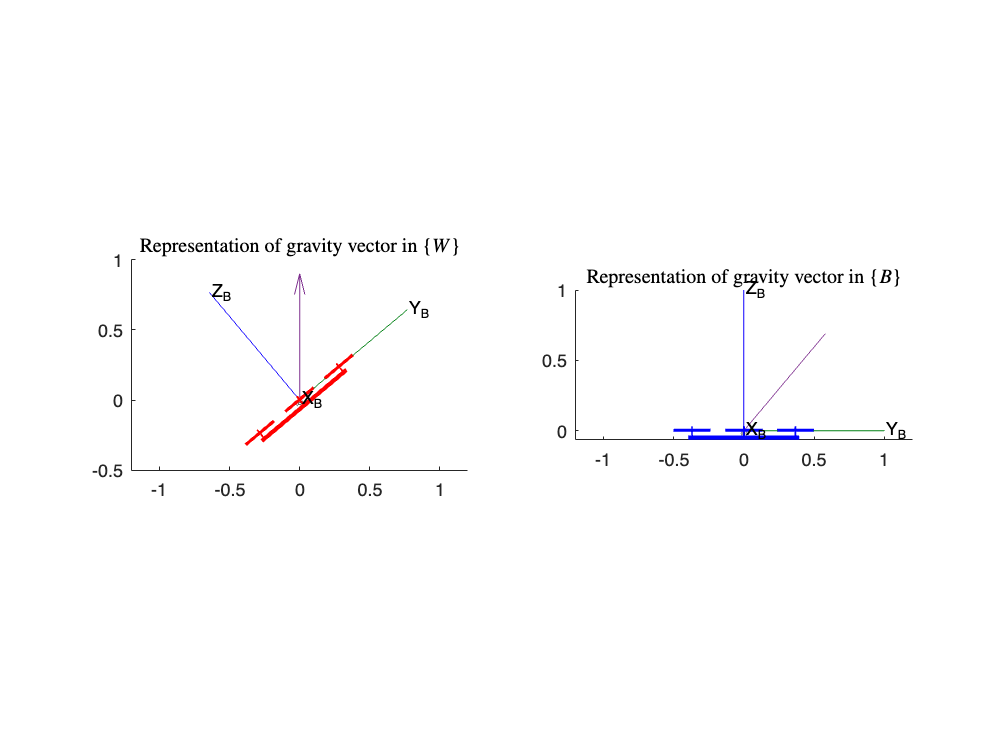

alpha = 40*pi/180;    %rotation angle
v = [1 0 0]; %rotation vector

S = [0   -v(3)  v(2);    %skew-symmetric form of rotation vector
     v(3)  0   -v(1);
    -v(2)  v(1)  0];

% R = expm(S*alpha);
R = eye(3)+sin(alpha)*S+( 1-cos(alpha) )*S^2;    %Rodrigues' formula to determine R

gb = R'*[0 0 1]';

%plot figures
figure 
subplot(1,2,1),hold on
plotTransforms([0 0 0],rotm2quat(R),"MeshFilePath",'multirotor.stl',"MeshColor","red","FrameAxisLabels","on","FrameLabel","B")
quiver3(0,0,0,0,0,1,MaxHeadSize=0.5)
view(v)
axis equal,title('Representation of gravity vector in $\{W\}$',Interpreter='latex')
xlim([-1.2 1.2]),ylim([-1.2 1.2])
% legend('${^W{\bf g}}$','Interpreter','latex')

subplot(1,2,2),hold on
plotTransforms([0 0 0],[1 0 0 0],"MeshFilePath",'multirotor.stl',"MeshColor","blue","FrameAxisLabels","on","FrameLabel","B")
quiver3(0,0,0,gb(1),gb(2),gb(3),MaxHeadSize=0.5)
view(v)
axis equal,title('Representation of gravity vector in $\{B\}$',Interpreter='latex')
xlim([-1.2 1.2]),ylim([-1.2 1.2])

#### Example: Estimating roll and pitch from an accelerometer

The code block below shows an example of how accelerometers can be used to partially estimate orientation. Notably, this estimation scheme is only reliable when the rotation vector ${^W{\bf v}}$ does not have a $z$ component. 

We should notice that:

- increasing the accelerometer noise density results in a noisier estimate, but the mean is still correct;

- adding a non-zero $z$-axis component to ${^W\hat{\bf v}}$ (i.e. changing parameter `vz `in the code block below) will result in an unreliable orientation estimate;

- increasing the translational acceleration causes problems in the estimation scheme, based on the assumption that the accelerometer is only detecting the gravitational vector.

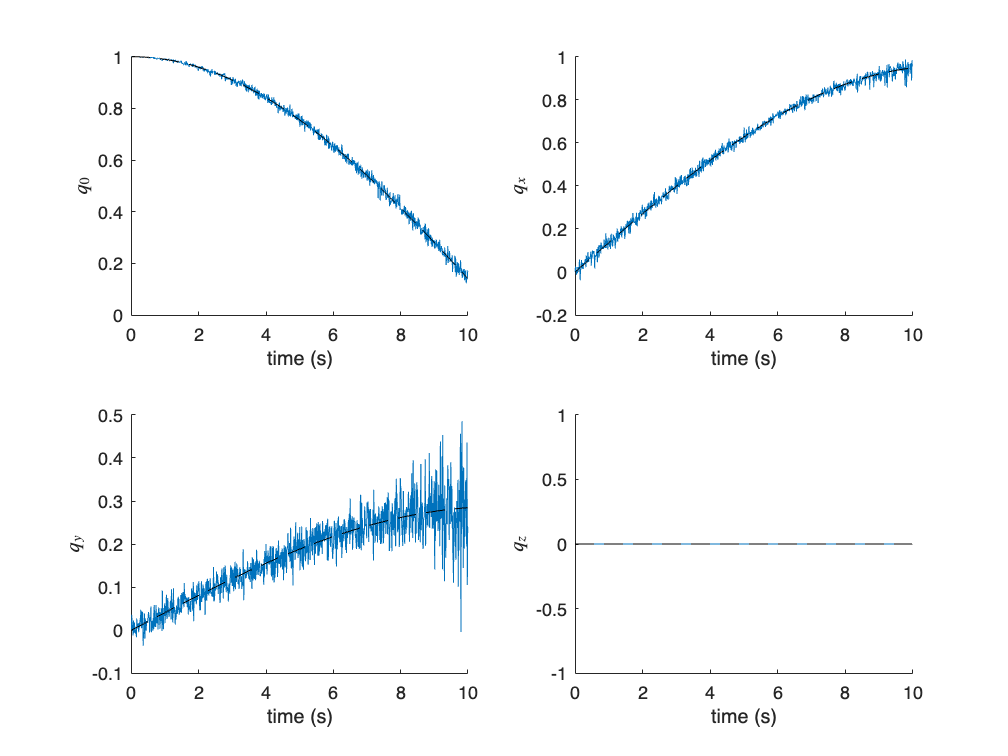

IMU = imuSensor;    %initialise simulated IMU
IMU.Accelerometer.NoiseDensity = 0.05311;    %set accelerometer noise density
acceleration = 0;

dT = 0.01;    %set IMU sample time
numSamples = 1000;    %set number of samples
t = (0:numSamples-1)*dT;    %set time vector

vx =1;    %set x component of rotation vector
vy =0.3;    %set y component of rotation vector
vz =0;    %set z component of rotation vector
v = [vx vy vz];
v = v/norm(v);    %normalise rotation vector

alpha = linspace(0,pi/1.1,numSamples);    %define array of rotation angles

q = zeros(numSamples,4);    %initialise quaternion array
q(1,1:4) = [1 0 0 0];

q_ = zeros(numSamples,4);    %initialise quaternion estimate array
q_(1,1:4) = [1 0 0 0];

gw = [0 0 1];    %gravity vector in {W}

for k=1:numSamples-1
    %actual
    q(k+1,:) = [cos(alpha(k+1)/2) sin(alpha(k+1)/2)*v];    %true quaternion

    R = quat2rotm(q(k+1,1:4));    %convert quaternion to rotation matrix

    %estimate
    [accel_meas,~] = IMU(acceleration*ones(1,3),zeros(1,3),R');    %generate accelerometer data
    accel_meas = accel_meas/norm(accel_meas);    %normalise accelerometer reading
   
    axb = cross(accel_meas,gw);    %cross product between accelerometer measurement and gravity vector in {W}
   
    % alpha_ = acos( dot(accel_meas,gw) );
    alpha_ = acos( accel_meas(3) );    %estimate rotation angle

    v_ = axb / sin( alpha_ );    %estimate rotation vector
    

    q_(k+1,1:4) = [cos(alpha_/2) sin(alpha_/2)*v_];    %estimate quaternion
    
end

%plot figures
figure
subplot(2,2,1),hold on
plot(t,q_(:,1)),plot(t,q(:,1),'--k'),ylabel('$q_0$',Interpreter='latex'),xlabel('time (s)')
subplot(2,2,2),hold on
plot(t,q_(:,2)),plot(t,q(:,2),'--k'),ylabel('$q_x$',Interpreter='latex'),xlabel('time (s)')
subplot(2,2,3),hold on
plot(t,q_(:,3)),plot(t,q(:,3),'--k'),ylabel('$q_y$',Interpreter='latex'),xlabel('time (s)')
subplot(2,2,4),hold on
plot(t,q_(:,4)),plot(t,q(:,4),'--k'),ylabel('$q_z$',Interpreter='latex'),xlabel('time (s)')

**  Question 6: **Determine whether a standalone accelerometer (and no additional sensors) could be used to estimate the orientation reliably if the true orientation was ${^W{\bf R}_B}=\left[\begin{array}{cc}    
-0.594 & -0.79 & -0.149\\
0.0998 & -0.256 & 0.961\\
-0.798 & 0.557 & 0.231
\end{array}\right].$ You can assume that no translational acceleration is experienced and that the accelerometer has been de-biased.

**Answer: **An accelerometer cannot be used to estimate this orientation as there is rotation taking place about $\hat{\bf z}_W$. 

%Answer block (if required)
R = [-0.594  -0.79  -0.149;
     0.0998  -0.256  0.961;
    -0.798    0.557  0.231]

R =    -0.5940   -0.7900   -0.1490
    0.0998   -0.2560    0.9610
   -0.7980    0.5570    0.2310


S = logm(R)

S =     0.0004   -1.9065    1.3900
    1.9074   -0.0004    0.8677
   -1.3915   -0.8671   -0.0008


alphaV = [-S(2,3) S(1,3) -S(1,2)]

alphaV =    -0.8677    1.3900    1.9065


#### Estimating translational motion

Assuming the orientation of the robot is known, we can separate out the acceleration from the accelerometer measurement. Given the de-biased measurement equation of


$${^B{\bf a}^\#}={^B{\bf a}}+{^B{\bf R}_W}{^W{\bf g}}+{\bf n}_a,$$


and known rotation matrix ${^B{\bf R}_W}$, we can estimate the translational acceleration using


$${^B{\bf a}^+}\approx{^B{\bf a}^\#}-{^B{\bf R}_W}{^W{\bf g}}.$$


The estimate of the corresponding world-frame acceleration follows as


$$\begin{array}{ll}
{^W{\bf a}^+}
&={^W{\bf R}_B}{^B{\bf a}^+},\\
&\approx {^W{\bf R}_B}\left({^B{\bf a}^\#}-{^B{\bf R}_W}{^W{\bf g}}\right),\\
&\approx {^W{\bf R}_B}{^B{\bf a}^\#}-{^W{\bf g}}.
\end{array}$$


We can then integrate this result to obtain the velocity and position estimates, namely


$${^W{\bf v}^+}(t)=\int_0^t {^W{\bf a}^+}(t)dt,$$


and


$${^W{\bf p}^+}(t)=\int_0^t {^W{\bf v}^+}(t)dt.$$


As with the orientation estimation using a gyroscope, the velocity and position estimates derived from the accelerometer will experience drift. In fact, the double integration of the estimate from acceleration to position means that the error accumulates quadratically, rather than linearly!

#### Example: Estimating velocity and position from an accelerometer

The code block below shows an example of how accelerometers can be used to estimate velocity and position in $\{W\}$. Note that this approach is only applicable when the orientation is known with sufficient accuracy.

We should notice that:

- increasing the accelerometer noise density results in a noisier acceleration estimate, which results in an ever-increasing drift on the velocity and position estimates.

- the velocity and position estimates are a lot less noisy than the acceleration estimate. This is because integration (going from say acceleration to velocity) can be thought of as a low-pass filter that attenuates high-frequency noise.

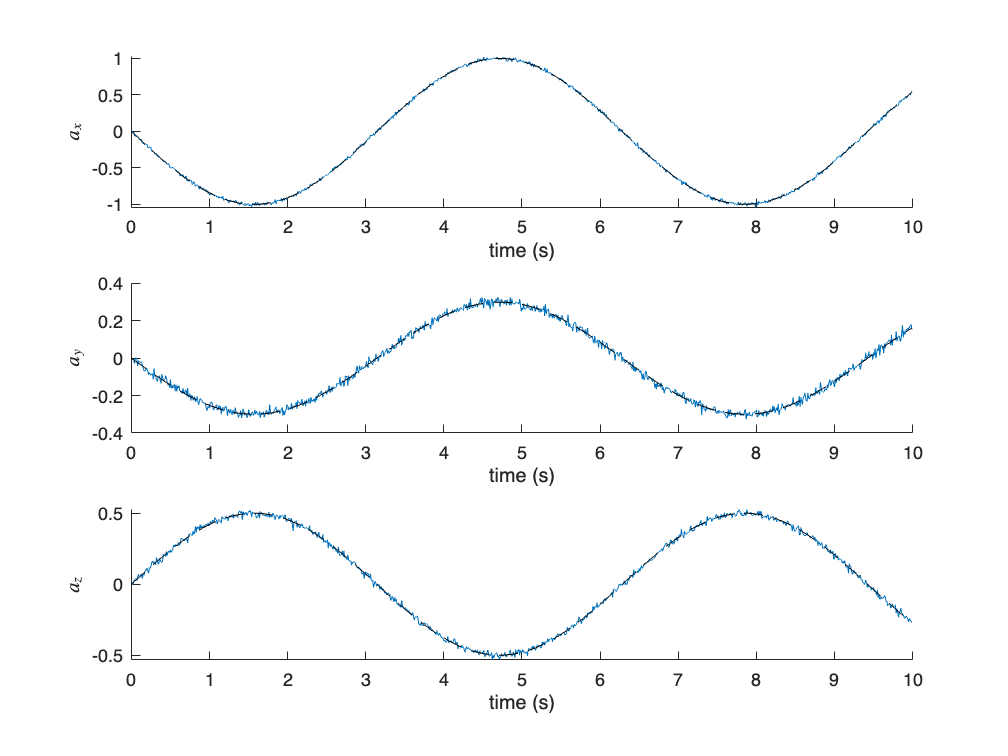

IMU = imuSensor;    %initialise simulated IMU
IMU.Accelerometer.NoiseDensity = 0.0021;    %set accelerometer noise density

vx =1;    %set x component of position vector
vy =0.3;    %set y component of position vector
vz =-0.5;    %set z component of position vector

dT = 0.01;    %set IMU sample time
numSamples = 1000;    %set number of samples
t = (0:numSamples-1)*dT;    %set time vector

p = sin(t).*[vx vy vz]';
v = cos(t).*[vx vy vz]';
a = -sin(t).*[vx vy vz]';

R = eye(3); %orientation assumed to be constant at identity
gw = [0 0 9.81]; 

a_ = zeros( size(a) );
v_ = zeros( size(v) );
v_(:,1) = v(:,1);
p_ = zeros( size(p) );

for k=2:numSamples
   
    %estimate
    [accel_meas,~] = IMU(a(:,k)',zeros(1,3),R');    %generate accelerometer data
   
    a_(:,k) = -(accel_meas'-gw'); %the negative sign is required, as MATLAB models the IMU using NED coordinates

    v_(:,k) = v_(:,k-1)+dT*a_(:,k); %obtain velocity estimate using Euler integration
    p_(:,k) = p_(:,k-1)+dT*v_(:,k); %obtain position estimate using Euler integration
    
end

%plot figures
figure
subplot(3,1,1),hold on
plot(t,a_(1,:)),plot(t,a(1,:),'--k'),ylabel('$a_x$',Interpreter='latex'),xlabel('time (s)')
subplot(3,1,2),hold on
plot(t,a_(2,:)),plot(t,a(2,:),'--k'),ylabel('$a_y$',Interpreter='latex'),xlabel('time (s)')
subplot(3,1,3),hold on
plot(t,a_(3,:)),plot(t,a(3,:),'--k'),ylabel('$a_z$',Interpreter='latex'),xlabel('time (s)')

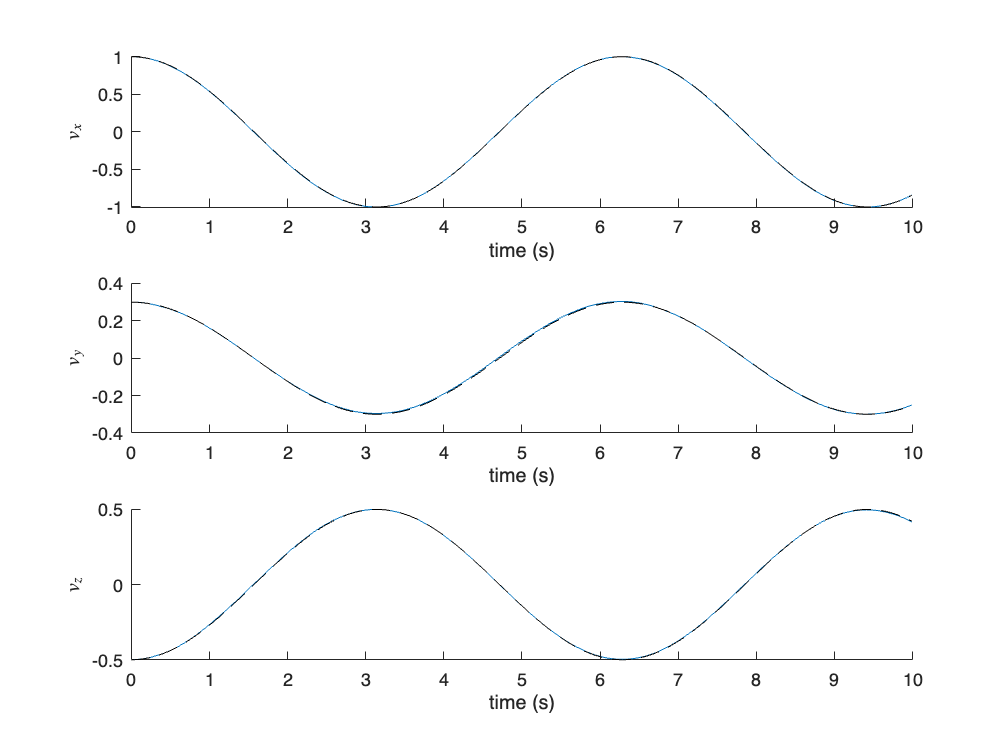


figure
subplot(3,1,1),hold on
plot(t,v_(1,:)),plot(t,v(1,:),'--k'),ylabel('$v_x$',Interpreter='latex'),xlabel('time (s)')
subplot(3,1,2),hold on
plot(t,v_(2,:)),plot(t,v(2,:),'--k'),ylabel('$v_y$',Interpreter='latex'),xlabel('time (s)')
subplot(3,1,3),hold on
plot(t,v_(3,:)),plot(t,v(3,:),'--k'),ylabel('$v_z$',Interpreter='latex'),xlabel('time (s)')

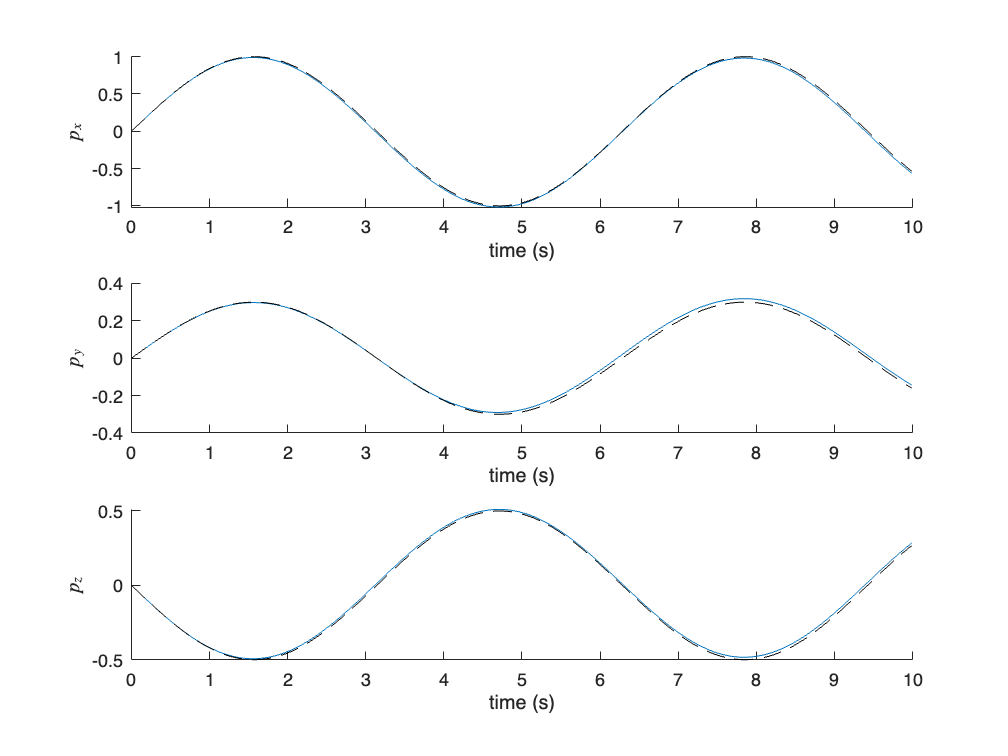


figure
subplot(3,1,1),hold on
plot(t,p_(1,:)),plot(t,p(1,:),'--k'),ylabel('$p_x$',Interpreter='latex'),xlabel('time (s)')
subplot(3,1,2),hold on
plot(t,p_(2,:)),plot(t,p(2,:),'--k'),ylabel('$p_y$',Interpreter='latex'),xlabel('time (s)')
subplot(3,1,3),hold on
plot(t,p_(3,:)),plot(t,p(3,:),'--k'),ylabel('$p_z$',Interpreter='latex'),xlabel('time (s)')

### Magnetometers

The key element of most modern magnetometers is a Hall-effect sensor; a semiconductor device that produces a voltage proportional to the magnetic field intensity in a direction normal to the current flow. Typically three Hall-effect sensors are packaged together and arranged so that their sensitive axes are orthogonal. The three outputs of such a tri-axial magnetometer are the components of the Earth’s magnetic field intensity vector measured in $\{B\}$.

Magnetometers are conceptually similar to accelerometers in that one can determine the rotation required to align a body-frame measurement of magnetic north to the world-frame counterpart. However, unlike an accelerometer, magnetometers do not measure translational accelerations, which means that the sensors can still be used to estimate orientation while experiencing arbitrary motion. The downside of magnetometers is that they are sensitive to electromagnetic interference, which is a natural by-product of electric motors, among other electronic devices.

#### Measurement equation

Assuming the world-frame $x$-axis points in the direction of magnetic north, the magnetic intensity vector in $\{W\}$ is given by


$${^W{\bf m}}= B\left[\begin{array}{cc}    \cos I \\ 0 \\ \sin I     \\ \end{array}\right],$$


where $B$ is the magnetic field intensity and $I$is the inclination angle, which is dependent on where the sensor is on the earth.

The measurement equation of a magnetometer is given by


$${^B{\bf m}^\#}={^B{\bf m}}+{\bf b}_m+{\bf n}_m.$$


As with the accelerometer, the magnetometer bias term varies slowly over time and can usually be determined approximately as a constant during a calibration process. Assuming this is performed, the resulting measurement equation becomes


$${^B{\bf m}^\#}={^B{\bf m}}+{\bf n}_m.$$


#### Estimating orientation

Orientation can be partially estimated using a magnetometer. Referring to the equation above, the measurement equation can be expressed as


$$\begin{array}{ll}
{^B{\bf m}^\#}
&={^B{\bf m}}+{\bf n}_m,\\
&={^B{\bf R}_W}{^W{\bf m}}+{\bf n}_m,\\
\end{array}$$


which takes a similar form to the accelerometer measurement model when there is no translational motion. It is common to normalise both the known magnetic intensity vector and magnetometer measurement, in order to remove the dependence on $B$:


$$\begin{array}{ll}
{^B\hat{\bf m}^\#}
&={^B\hat{\bf m}}+{\bf n}_m,\\
&={^B{\bf R}_W}{^W\hat{\bf m}}+{\bf n}_m,\\
\end{array}$$


The normalised world-frame magnetic intensity vector is given by


$${^W\hat{\bf m}}= \left[\begin{array}{cc}    \cos I \\ 0 \\ \sin I     \\ \end{array}\right],$$


which can be measured from the calibrated magnetometer when $\{B\}$ and $\{W\}$ are aligned, namely, when ${^B{\bf R}_W}={\bf I}$. 

Recalling the relationship between the cross product and exponential coordinates, as introduced in **Chapter 3**, we can determine the rotation vector and angle of rotation that in general maps ${^B\hat{\bf m}^\#}$ to ${^W\hat{\bf m}}$ using


$${^B\hat{\bf m}^\#} \times {^W\hat{\bf m} = \sin\alpha^+ \hat{\bf v}^+.$$


The exponential coordinates corresponding to the detected magnetometer rotation is given by $\alpha^+\hat{\bf v}^+$ and can be recovered using


$$\begin{array}{ll}
\alpha^+ 
&= \cos^{-1}\left({^B\hat{\bf m}^\#} \cdot {^W\hat{\bf m}}\right),
\end{array}$$


and


$${^W\hat{\bf v}}^+=\frac{1}{\sin\alpha^+} {^B\hat{\bf m}^\#} \times {^W\hat{\bf m}.

$$


Finally, the rotation matrix estimate can be formed from the axis-angle representation by


$${^W{\bf R}^+_B}={\bf e}^{\lfloor  {^W{\bf v}^+}\rfloor \alpha^+}.$$


Analogous to the accelerometer, the magnetometer cannot detect rotations about ${^W\hat{\bf m}}$. For this reason, the one cannot solely rely on a magnetometer to estimate generalised orientation.

## Normalisation

The process of estimating orientation using rotation matrices or quaternions requires iterative multiplication of matrices or vectors, respectively. Given that the hardware (e.g. microcontroller or computer) used to make these computations has finite precision, subsequent multiplication operations, followed by numerical truncation, will eventually result in rotation matrices not being orthogonal, or quaternions not being unitary (having unit length). To compensate for this, we can perform a normalisation step at regular intervals, such as after every few samples (the frequency would depend on the numerical precision of the hardware).

### **Rotation matrices**

The basic concept of rotation matrix normalisation is to enforce each column of the matrix to be orthogonal to the other columns, with unit magnitudes (to preserve the orthogonal property of a rotation matrix). This is done by first selecting one column of  


$${{\mathbf R}}=[{\mathbf c}_1  ~~{\mathbf c}_2 ~~ {\mathbf c}_3]$$


such as column three, ${\mathbf c}_3$, and assume that the direction is correct, namely


$$\begin{array}{cc}    {\mathbf c}^{'}_3={\mathbf c}_3.\\ \end{array}$$


The (updated) first column, ${\bf c}_1^{'}$, is then set to be orthogonal to the last two columns


$$\begin{array}{cc}    {\mathbf c}^{'}_1={\mathbf c}_2 \times {\mathbf c}^{'}_3.\\ \end{array}$$


Given that the last two columns may not have been orthogonal, we define the second column to be orthogonal to the first and third column


$$\begin{array}{cc}    {\mathbf c}^{'}_2={\mathbf c}^{'}_3 \times {\mathbf c}^{'}_1.\\ \end{array}$$


Finally, each column is individually normalised, in order to preserve unit length


$$\begin{array}{cc}    \hat{\mathbf c}^{'}_i=\frac{ {\mathbf c}^{'}_i }{|{\mathbf c}^{'}_i|},  \forall i\in [1,3].\\ \end{array}$$


The resulting normalised rotation matrix follows as  


$${{\mathbf R}^{'}}=[\hat{\mathbf c}^{'}_1 ~~ \hat{\mathbf c}^{'}_2 ~~ \hat{\mathbf c}^{'}_3],$$


which now adheres to the orthogonality requirements of SO(3).

**  Question 7: **Given the unnormalised rotation matrix of ${{\bf R}}=\left[\begin{array}{cc}    
-0.5 & -0.8 & -0.2\\
0.1 & -0.3 & 1\\
-0.8 & 0.6 & 0.2
\end{array}\right]$, determine whether performing rotation matrix normalisation in different orders will result in the same normalised rotation matrix. 

**Answer: **Following different orders of normalisation will, in general, result in different normalised rotation matrices.

%Answer block (if required)
R = [-0.5 -0.8 -0.2; 0.1 -0.3 1; -0.8 0.6 0.2]

R =    -0.5000   -0.8000   -0.2000
    0.1000   -0.3000    1.0000
   -0.8000    0.6000    0.2000


c1 = R(:,1);
c2 = R(:,2);
c3 = R(:,3);

%c3->c1->c2
c3_ = c3;
c1_ = cross(c2,c3_);
c2_ = cross(c3_,c1_);
c1_ = c1_/norm(c1_);
c2_ = c2_/norm(c2_);
c3_ = c3_/norm(c3_);
R_ = [c1_ c2_ c3_]

R_ =    -0.6084   -0.7699   -0.1925
    0.0369   -0.2697    0.9623
   -0.7928    0.5783    0.1925


%c3->c2->c1
c3_ = c3;
c2_ = cross(c3_,c1);
c1_ = cross(c2_,c3_);
c1_ = c1_/norm(c1_);
c2_ = c2_/norm(c2_);
c3_ = c3_/norm(c3_);
R_ = [c1_ c2_ c3_]

R_ =    -0.5197   -0.8324   -0.1925
    0.0664   -0.2639    0.9623
   -0.8518    0.4873    0.1925


### **Quaternions**

As with the rotation matrix update, we require normalisation of the quaternion in order to maintain the unitary structure. In the case of the quaternion, normalisation simply requires dividing all elements by the quaternion norm


$$\begin{array}{cc}{{\mathbf q}} = \frac{{{\mathbf q}}}{|{{\mathbf q}}|}, \end{array}$$


which is also computationally more efficient than the rotation matrix counterpart.

**  Question 8: **Determine the normalised quaternion form of ${{\bf q}}=\left[\begin{array}{cc}    
-0.5 & -0.8 & -0.2 & 0.3
\end{array}\right]^T$.

**Answer: **${\bf q} = \left[\begin{array}{c}-0.495\\-0.792\\-0.198\\0.297\end{array}\right]$

%Answer block (if required)
q = [-0.5 -0.8 -0.2 0.3]';
q = q/norm(q);
vpa(q,3)

$$ans = \left(\begin{array}{c} -0.495\\ -0.792\\ -0.198\\ 0.297 \end{array}\right)$$

## Sensor fusion

The previous section has shown that simply using a gyroscope, accelerometer, or magnetometer on its own is not sufficient to fully and reliably estimate orientation. Sensor fusion is a process of making use of multiple measurements in a strategic way, such that the appealing qualities of each measurement is used and the unappealing qualities discarded, or compensated for by the other sensor measurements. While there are many types of sensor fusion algorithms, we will consider two in particular that are computationally lightweight but also highly compatible with IMU modules, among other sensors. 

### TRIAD algorithm

The **TRIAD (tri-axial attitude determination) algorithm** was a popular approach use in spacecraft navigation for estimating the attitude given knowledge of two vector observations (such as based on the position of stars in space). Given two known vectors in the world frame, and two corresponding measurements in the body-frame, one can determine the unique rotation matrix that relates the two frames, assuming these two vector observations are not collinear (sitting on the same line). The TRIAD algorithm can take this concept one step further by exploiting the property of orthogonal matrices, where the matrix inverse is equivalent to its transpose. 

The method will be presented here using accelerometer and magnetometer information, but note that this approach can extend to any sensor that has inertial-frame sensor observations.

#### Derivation

Recall that the gravity vector in $\{W\}$ can be estimated from the translation-free accelerometer measurement using


$${^W\hat{\bf g}}\approx {^W{\bf R}_B}{^B\hat{\bf a}^\#}.$$


Similarly, the magnetic intensity vector in $\{W\}$ is given by


$${^W\hat{\bf m}}\approx {^W{\bf R}_B}{^B\hat{\bf m}^\#}.$$


Additionally, a fictitious third measurement can be constructed using the cross product of the accelerometer and magnetometer readings — ${^B\hat{\bf a}^\#}\times {^B\hat{\bf m}^\#}$ — which can also be mapped through the yet to be determined rotation matrix as


$${^W\hat{\bf c}^+}={^W{\bf R}^+_B}\left({^B\hat{\bf a}^\#}\times {^B\hat{\bf m}^\#}\right)\approx {^W\hat{\bf g}}\times {^W\hat{\bf m}^}.$$


Stacking together the three equations above into matrix form yields


$$\left[\begin{array}{ccc}
 {^W\hat{\bf g}} & \vdots {^W\hat{\bf m}} & \vdots {^W\hat{\bf c}} \end{array}\right]
= {^W{\bf R}^+_B}
\left[ \begin{array}{ccc}

{^B\hat{\bf a}^\#} &\vdots {^B\hat{\bf m}^\#} &\vdots {^B\hat{\bf a}^\#}\times {^B\hat{\bf m}^\#} \end{array}\right].$$


Note that the $\vdots$ icon is used to clearly separate the matrix columns. The rotation matrix, ${^W{\bf R}^+_B}$, can then be calculated by rearranging the equation above, namely


$$
{^W{\bf R}^+_B}=

\left[\begin{array}{ccc}
 {^W\hat{\bf g}} & \vdots{^W\hat{\bf m}} &\vdots {^W\hat{\bf c}} \end{array}\right]
\left[ \begin{array}{ccc}

{^B\hat{\bf a}^\#} & \vdots{^B\hat{\bf m}^\#} & \vdots{^B\hat{\bf a}^\#}\times {^B\hat{\bf m}^\#} \end{array}\right]^{-1}.$$


**  Question 9: **Determine the rotation matrix estimate corresponding to an accelerometer and magnetometer measurements of ${^B{\bf a}^\#}=[1.1009~~-6.4374~~7.3067]^T$ and ${^B{\bf m}^\#}=[-5.7781~~30.806~~6.4378]^T$. You can assume that both sensors have been de-biased and no translational acceleration is being experienced. The magnetic intensity vector in $\{W\}$ is given by ${^W{\bf m}}=[27.5550 ~~  -2.4169~~  -16.0849]^T$, and the IMU experiences a gravitational acceleration of $g=9.8$m/s$^2$.

**Answer: **${^W{\bf R}_B}=\left[\begin{array}{ccc}-0.229 & 0.713 & 0.663\\-0.967 & -0.245 & -0.0703\\0.112 & -0.657 & 0.746\end{array}\right]$

%Answer block (if required)
gw = [0 0 9.8]';
gw = gw/norm(gw)

gw =      0
     0
     1



mw = [27.5550   -2.4169  -16.0849]';
mw = mw/norm(mw)

mw =     0.8612
   -0.0755
   -0.5027



gb = [1.1009 -6.4374 7.3067]';
gb = gb/norm(gb);

mb = [-5.7781 30.806 6.4378]';
mb = mb/norm(mb);

R_ = [gw mw cross(gw,mw)]/[gb mb cross(gb,mb)]

R_ =    -0.2289    0.7130    0.6627
   -0.9669   -0.2451   -0.0703
    0.1123   -0.6569    0.7456


vpa(R_,3)

$$ans = \left(\begin{array}{ccc} -0.229 & 0.713 & 0.663\\ -0.967 & -0.245 & -0.0703\\ 0.112 & -0.657 & 0.746 \end{array}\right)$$


mw_ = R_*mb

mw_ =     0.8612
   -0.0755
   -0.5027


gw_ = R_*gb

gw_ =          0
   -0.0000
    1.0000


#### Inverse-free approach

Computation of a $3\times 3$ matrix inverse can be computationally heavy for low-cost hardware, so an elegant alternative was developed that circumvents this. The basic idea is to ensure that all matrices used in the calculation remain orthogonal. This means that the transpose of the matrix can be calculated when determining the inverse, which is computationally light.

The process begins by selecting a measurement and observation pair that will remain unchanged, such as


$${^W\hat{\bf g}^+}= {^W{\bf R}_B}{^B\hat{\bf a}^\#}.$$


A second "measurement" is then constructed such that it is orthogonal to ${^B\hat{\bf a}^\#}$ and ${^B\hat{\bf m}^\#}$, but also is unitary, namely


$${^B\hat{\bf s}^\#}=\frac{ {^B\hat{\bf a}^\#}\times{^B\hat{\bf m}^\#} }{\left| {^B\hat{\bf a}^\#}\times{^B\hat{\bf m}^\#} \right|}.$$


The corresponding observation in $\{W\}$ is given by


$${^W\hat{\bf s}^+}=\frac{ {^W\hat{\bf g}^+}\times{^W\hat{\bf m}^+} }{\left| {^W\hat{\bf g}^+}\times{^W\hat{\bf m}^+} \right|}.$$


The final unitary measurement is constructed such that ${^B\hat{\bf a}^\#}$ and ${^B\hat{\bf s}^\#}$ are orthogonal, which is given by


$${^B\hat{\bf z}^\#}= \frac{ {^B\hat{\bf a}^\#}\times{^B\hat{\bf s}^\#} }{ \left|{^B\hat{\bf a}^\#}\times{^B\hat{\bf s}^\#} \right|},$$


with the corresponding world-frame observation following as


$${^W\hat{\bf z}^+}=\frac{ {^W\hat{\bf g}^+}\times{^W\hat{\bf s}^+} }{\left| {^W\hat{\bf g}^+}\times{^W\hat{\bf s}^+} \right|}.$$


We can then represent these relationships in matrix form as


$$\begin{array}{ll}
\left[\begin{array}{ccc}
 {^W\hat{\bf g}^+} &\vdots {^W\hat{\bf s}^+} &\vdots {^W\hat{\bf z}^+} \end{array}\right]
&= {^W{\bf R}^+_B}
\left[ \begin{array}{ccc}

{^B\hat{\bf a}^\#} &\vdots {^B\hat{\bf s}^\#} &\vdots {^B\hat{\bf z}^\#} \end{array}\right],\\
&= {^W{\bf R}^+_B}
\left[ \begin{array}{ccc}

{^B\hat{\bf a}^\#} &\vdots {^B\hat{\bf s}^\#} &\vdots \frac{ {^B\hat{\bf a}^\#}\times{^B\hat{\bf s}^\#} }{ \left|{^B\hat{\bf a}^\#}\times{^B\hat{\bf s}^\#} \right|} \end{array}\right].

\end{array}$$


Importantly, the matrix post-multiplying ${^W{\bf R}^+_B}$ in the equation above is orthogonal, which allows us to determine the rotation matrix estimate as


$$\begin{array}{ll}
{^W{\bf R}^+_B} = 
\left[\begin{array}{ccc}
 {^W\hat{\bf g}^+} & \vdots{^W\hat{\bf s}^+} & \vdots{^W\hat{\bf z}^+} \end{array}\right]
\left[ \begin{array}{ccc}

{^B\hat{\bf a}^\#} & \vdots{^B\hat{\bf s}^\#} &\vdots \frac{ {^B\hat{\bf a}^\#}\times{^B\hat{\bf s}^\#} }{ \left|{^B\hat{\bf a}^\#}\times{^B\hat{\bf s}^\#} \right|} \end{array}\right]^T.



\end{array}$$


#### Example: TRIAD algorithm

The code block below shows an example of how accelerometers and magnetometers can be used together to fully estimate orientation. Notably, this estimation scheme is only reliable when there is negligible translational acceleration.

We should notice that:

- increasing the accelerometer or magnetometer noise density results in a noiser estimate, but the mean is still correct;

- regardless of the rotation vector, the orientation can be estimated reliably;

- increasing the translational acceleration causes problems in the estimation scheme, based on the assumption that the accelerometer is only detecting the gravitational vector.

IMU = imuSensor("IMUType","accel-mag");    %initialise IMU that has an accelerometer and magnetometer
IMU.Accelerometer.NoiseDensity = 0.00851;    %set accelerometer noise
IMU.Magnetometer.NoiseDensity = 0.01281;    %set magnetometer noise

acceleration = 0;    %set translation acceleration experienced by IMU

dT = 0.01;    %sampling time of IMU
numSamples = 1000;    %number of samples
t = (0:numSamples-1)*dT;    %define time vector for plotting

v = [1 -0.3 .5];    %arbitrary rotation vector (not necessarily normalised)
v = v/norm(v);      %normalise rotation vector
omega = linspace(0,pi/20,numSamples);    %angular velocity magnitude
q = zeros(numSamples,4);    %initialised quaternion array
q(1,1:4) = [1 0 0 0];

q_ = zeros(numSamples,4);    %initialised quaternion estimate array
q_(1,1:4) = [1 0 0 0];

gw = [0 0 1];    %gravity vector in {W}
mw = IMU.MagneticField;    %magnetometer vector in {W}

sw = cross(gw,mw);    %cross product of gravity vector and magnetic intensity vector
sw = sw/norm(sw);     %normalised form

zw = cross(gw,sw);    %cross product of gravity vector and new vector above
zw = zw/norm(zw);     %normalised form

for k=1:numSamples-1

    %true orientation
    alpha = omega(k)*dT;    %rotation angle at sample instance k
    theta = alpha*v;        %exponential coordinate at sample instance k
    dq = [cos(alpha/2) sin(alpha/2)*v];    %incremental quaternion
    q(k+1,:) = quatmultiply(q(k,:),dq);    %updated quaternion

    R = quat2rotm(q(k+1,1:4));    %convert quaternion to rotation matrix

    %measurement
    [accel_meas,mag_meas] = IMU(acceleration*ones(1,3),omega(k)*v,R');    %generate accelerometer and magnetometer data
    ab = accel_meas/norm(accel_meas);    %normalised accelerometer data
    mb = mag_meas/norm(mag_meas);    %normalised magnetometer data
    
    sb = cross(ab,mb);    %calculate cross product of accelerometer and magnetometer readings
    sb = sb/norm(sb);     %normalise
    
    zb = cross(ab,sb);    %calculate cross product of accelerometer reading and sb
    zb = zb/norm(zb);     %normalise

    C = [ab' sb' zb'];    %populate matrix C with measurements in {B}
    A = [gw' sw' zw'];    %populate matrix A with observations in {W}

    R_ = A*C';            %estimate rotation matrix 
    
    q_(k+1,:) = rotm2quat(R_);    %convert rotation matrix to quaternion
end

%plot figure
figure
subplot(2,2,1),hold on
plot(t,q_(:,1)),plot(t,q(:,1),'--k'),ylabel('$q_0$',Interpreter='latex'),xlabel('time (s)')
subplot(2,2,2),hold on
plot(t,q_(:,2)),plot(t,q(:,2),'--k'),ylabel('$q_x$',Interpreter='latex'),xlabel('time (s)')
subplot(2,2,3),hold on
plot(t,q_(:,3)),plot(t,q(:,3),'--k'),ylabel('$q_y$',Interpreter='latex'),xlabel('time (s)')
subplot(2,2,4),hold on
plot(t,q_(:,4)),plot(t,q(:,4),'--k'),ylabel('$q_z$',Interpreter='latex'),xlabel('time (s)')

**  Question 10: **Under what condition will the TRIAD algorithm not be able to fully estimate orientation?

**Answer: **When the magnetic intensity vector and gravitational vector are parallel or anti-parallel.

**  Question 11: **Upload your completed Virtual Lab .mlx file in Amathuba. Make sure to include your student number in the file name.